% MATLAB script to generate sinusoidal data for Verilog testbench

% Parameters
fs = 50e6;  % Sampling frequency (50 MHz)
t = 0:1/fs:1000/fs;  % Time vector for 64 samples

% Generate 1 MHz sinusoid
f_1 = 300e3;
f_2 = 6000e3;

sin_1 = round(2^24 * sin(2*pi*f_1*t));
sin_2 = round(2^23 * sin(2*pi*f_2*t));

cos_1 = round(2^24 * cos(2*pi*f_1*t));
cos_2 = round(2^23 * cos(2*pi*f_2*t));

sin_comp = sin_1 + sin_2;
cos_comp = cos_1 + cos_2;

% Generate 2 MHz sinusoid

% Write to text files
writematrix(sin_comp', 'sin_comp.txt', 'Delimiter', '\t');
writematrix(cos_comp', 'cos_comp.txt', 'Delimiter', '\t');

filter_out = typecast(uint32(readmatrix("output_lpf.txt", 'Delimiter', '\t')), 'int32')'*2^-6

filter_out = 1×999 int32 row vector
     786432    2238722    3353071    4036604    4396419    4682827    5154885    5941118    6970932    8013898    8805625    9191985    9213533    9084338    9076736    9374447    9973709   10685999   11240886   11433257   11235113   10811343   10430920   10321664   10547295   10973433   11340964   11407015   11077113   10456903    9795374    9350387    9249386    9420800    9633326    9621786    9231354    8501959    7647120    6938684    6559947    6506771    6590312    6539859    6150059    5392710    4432531    3538349    2937867    2694706



alpha = 2^-4

alpha = 0.0625

wc = asec((-alpha^2 + 2*alpha-2)/(2*(alpha-1)));
fc=wc/(2*pi)*fs

fc = 5.1323e+05

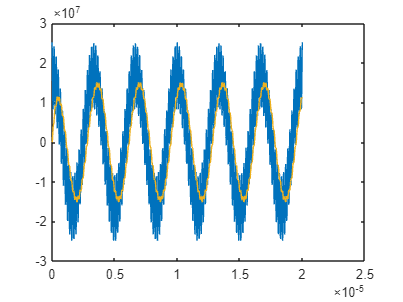

tustin_num = alpha/2*[1 1];
tustin_den = [1 -(1-alpha)];
tustin_iir = dsp.IIRFilter('Numerator',tustin_num,'Denominator',tustin_den);
%fvtool(tustin_iir,'Fs',fs);

reset(tustin_iir)
filter_ideal = tustin_iir(cos_comp')';
reset(tustin_iir)

figure();
plot (t, cos_comp)
hold on
plot (t, [0, 0, filter_ideal(1:end-2)])
plot (t, [0, 0, filter_out])

max([0, 0, filter_ideal(1:end-2)] - double([0, 0, filter_out]))

ans = 0.4299